## Introduction

In this scrip, i try to make my data more visible.

I will produce several image about data.

## Import data

create storage

RMSstorage=zeros(1001,36,5);
delta=0.01;
if delta==0.1
    zetastore=[1.25,2.5,5,10,20,40];
elseif delta==0.01
    zetastore=[12.5,25,50,100,200,400];
end

import data

Total_experiment_number=3000;
row=1;
column=1;
for H=[0.6,0.7,0.8]
    for zeta=zetastore
        for psi=[zeta/1.25,zeta/2.5,zeta/5,zeta/10,zeta/20]
                load(['C:\Users\zhouquan\OneDrive\research\DNA随机游走模拟\数据模拟\v4_1\data\RMSdata.H=',num2str(H), ...
                    '.zeta=',num2str(zeta),'.psi=',num2str(psi),'.N=',num2str(Total_experiment_number),'.mat']);
                RMSstorage(:,row,column)=RMSX;
                column=column+1;
        end
        row=row+1;
        column=1;
    end
end

## Plotting

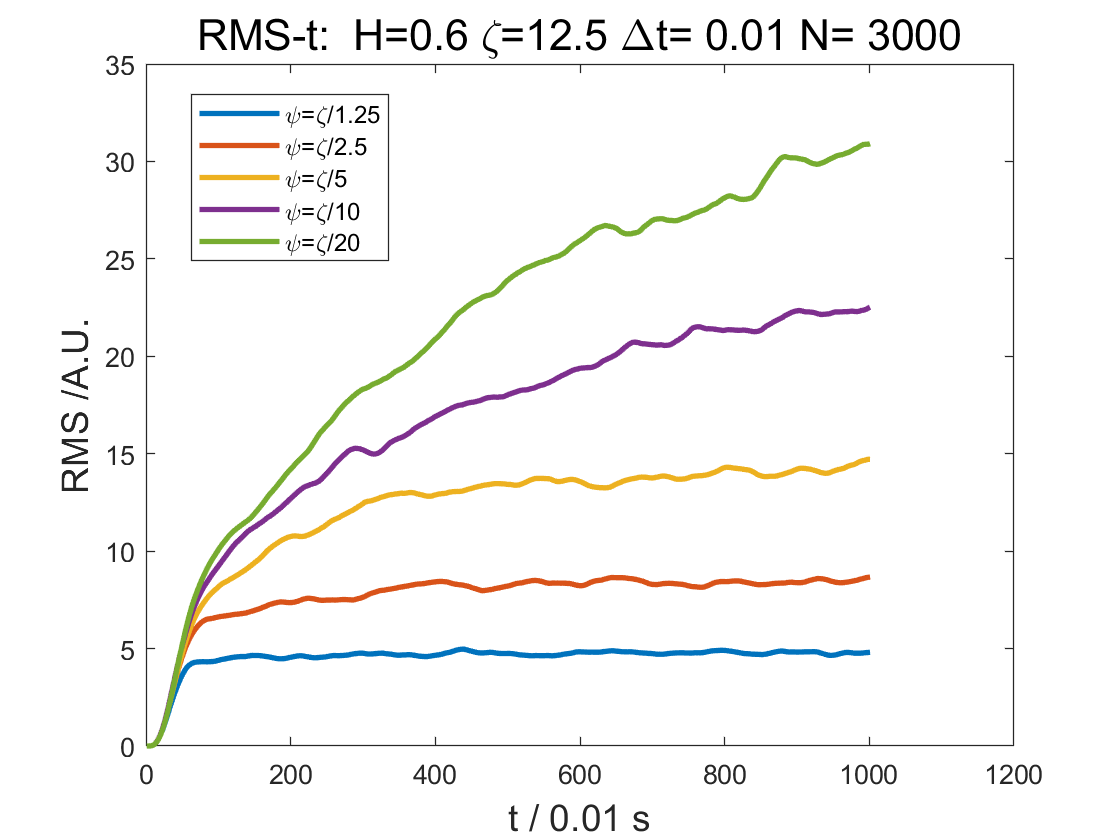

row = 2

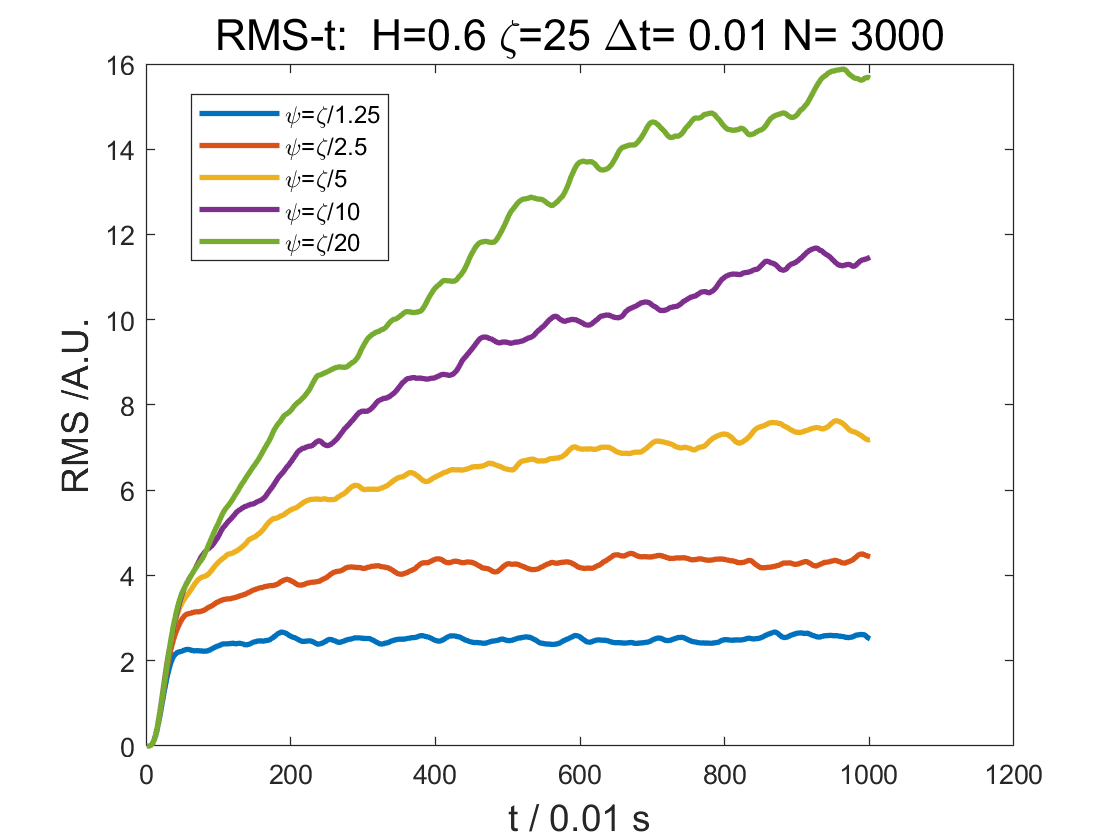

row = 3

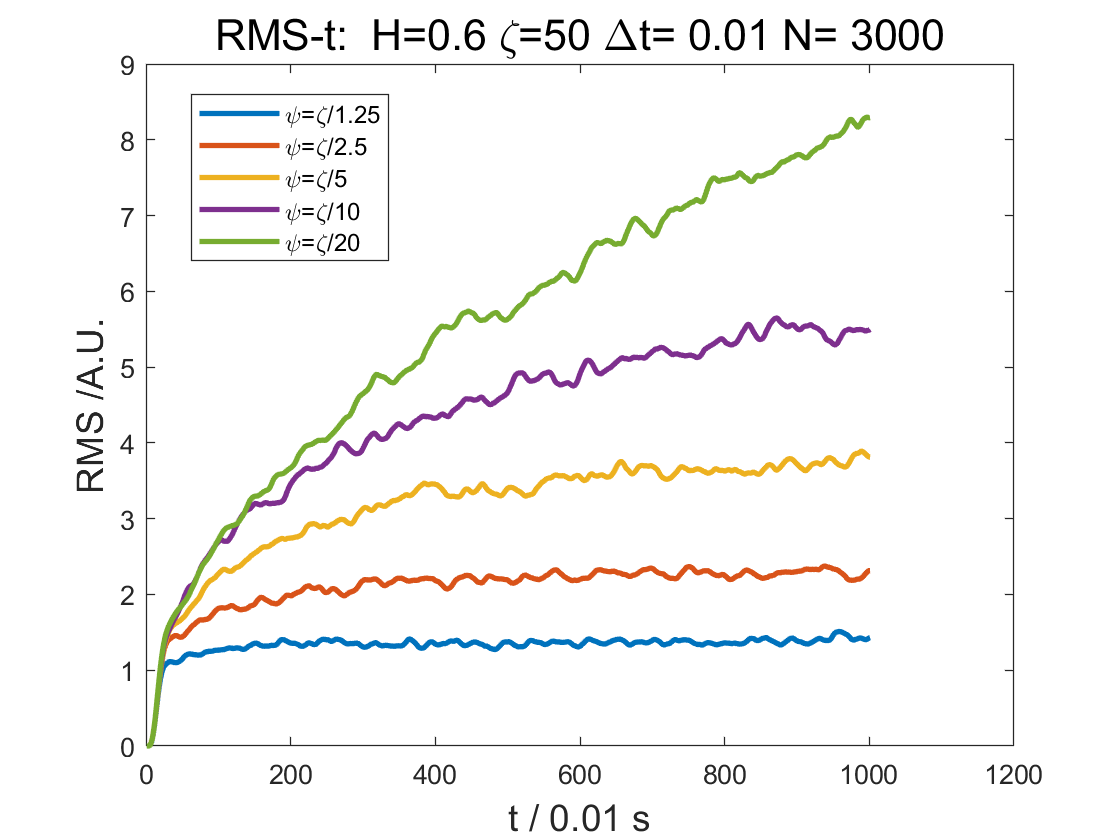

row = 4

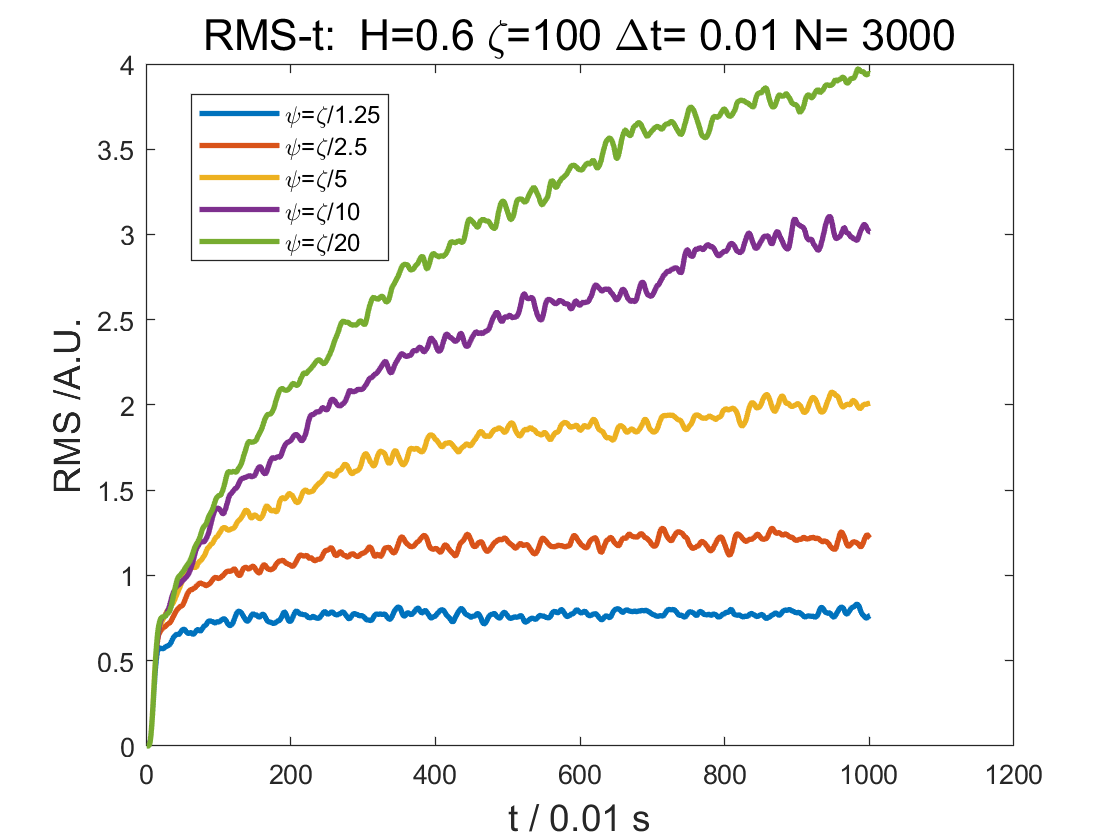

row = 5

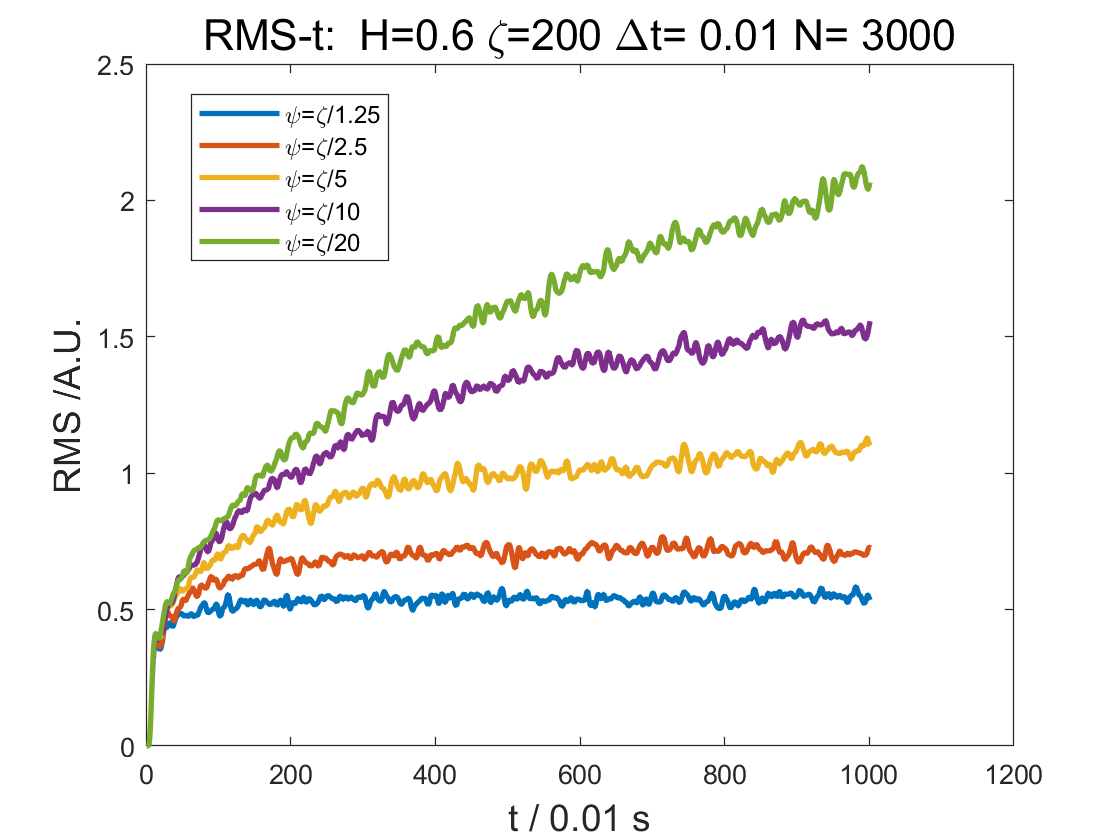

row = 6

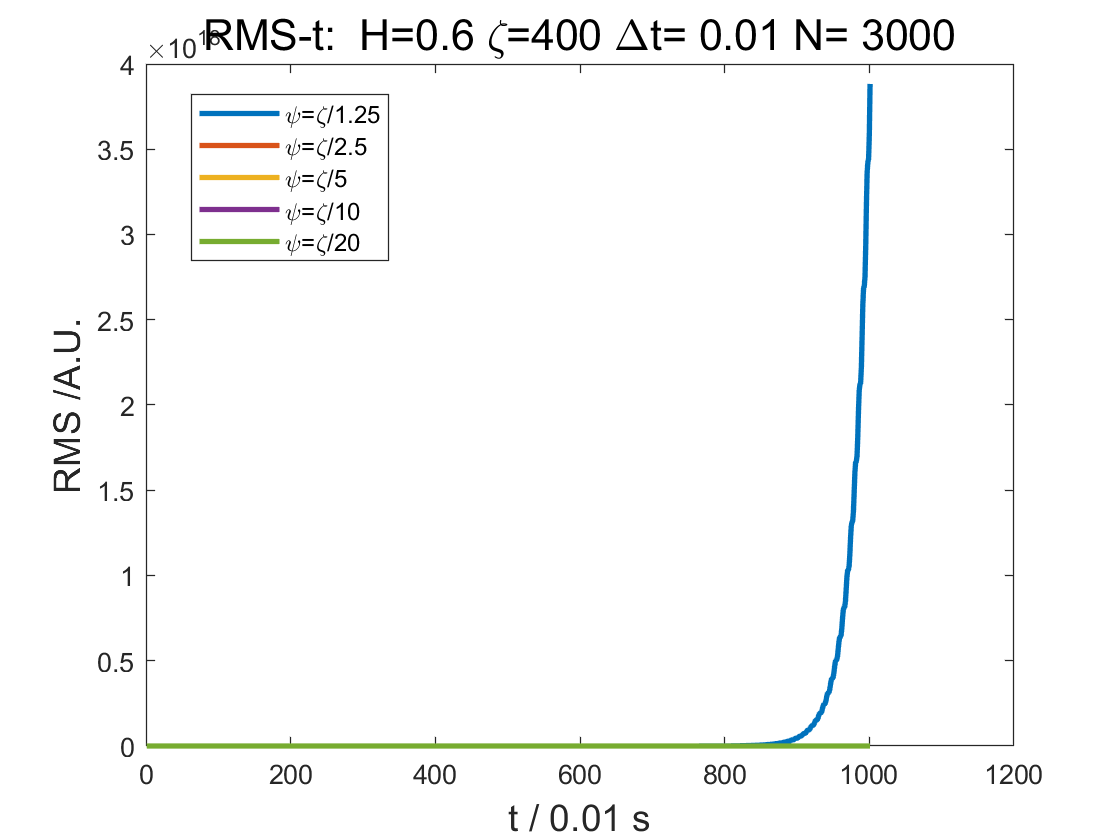

row = 7

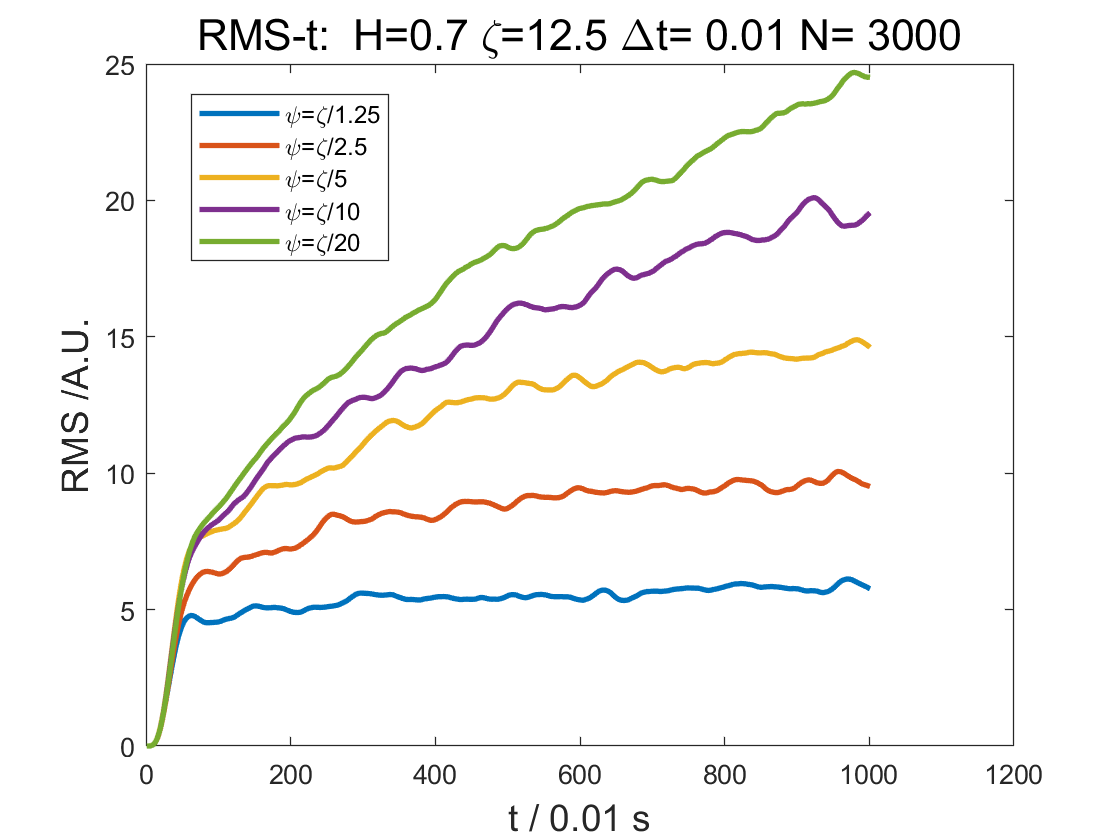

row = 8

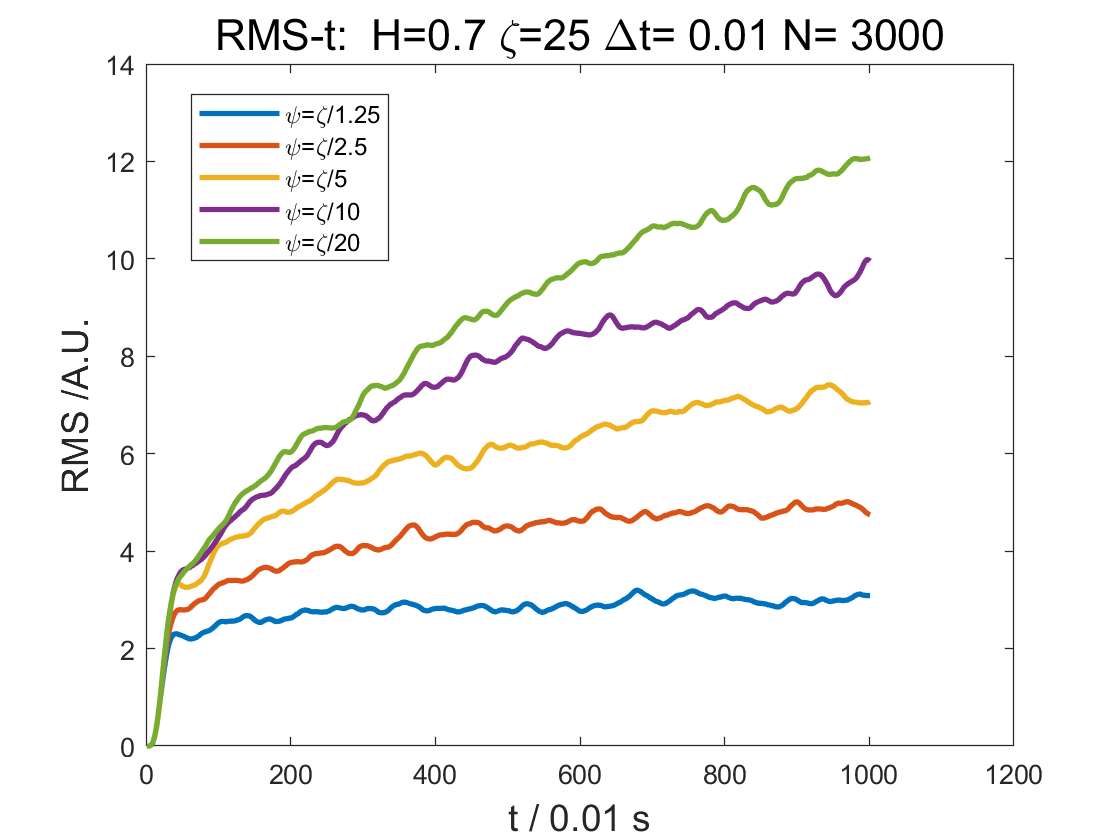

row = 9

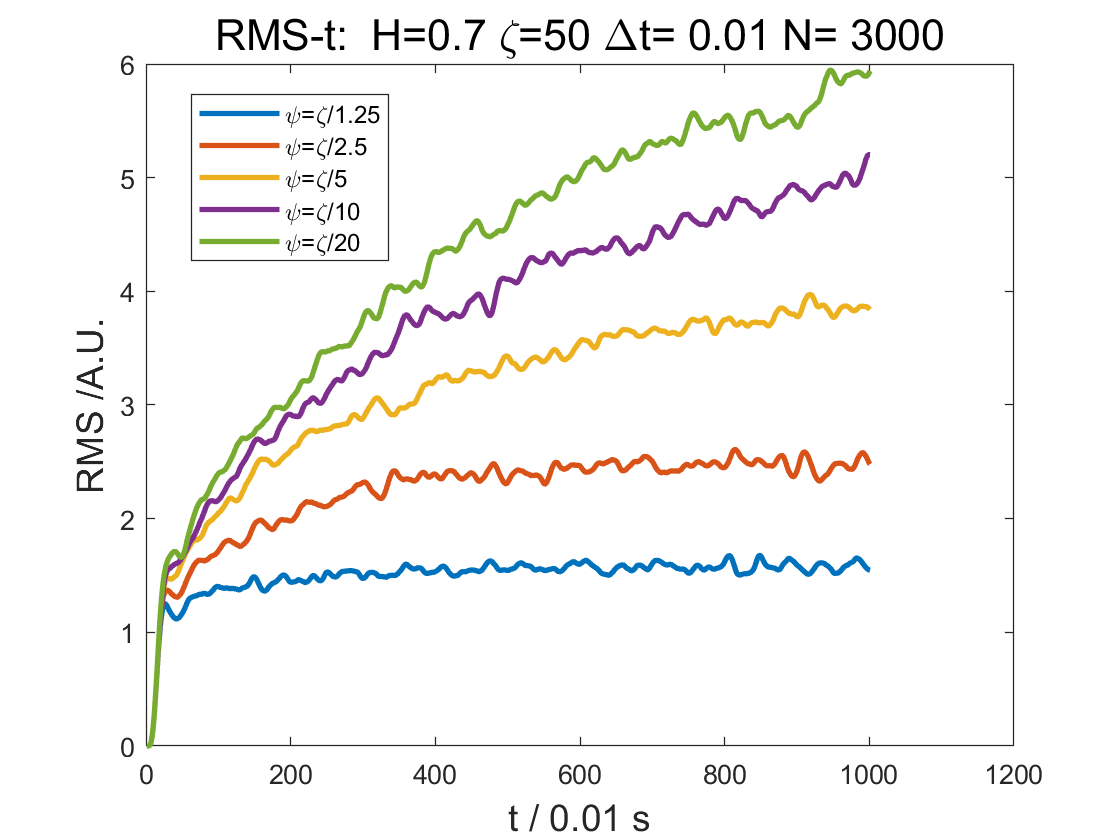

row = 10

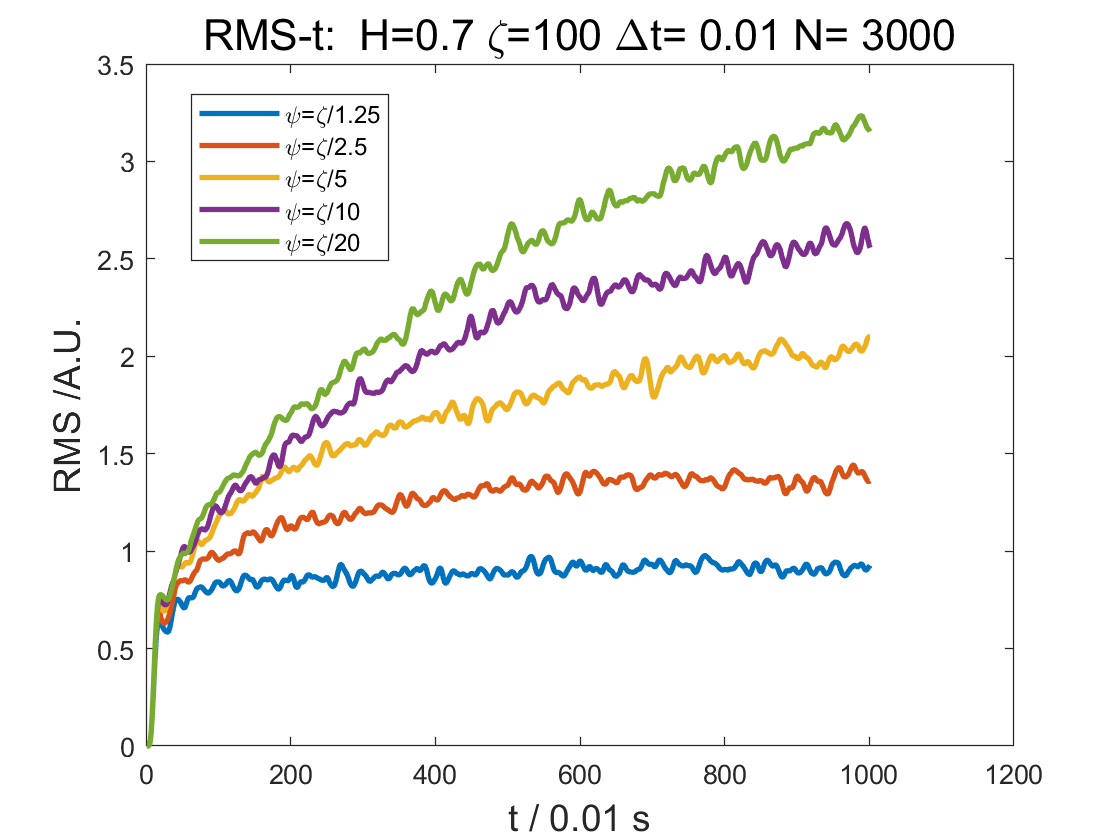

row = 11

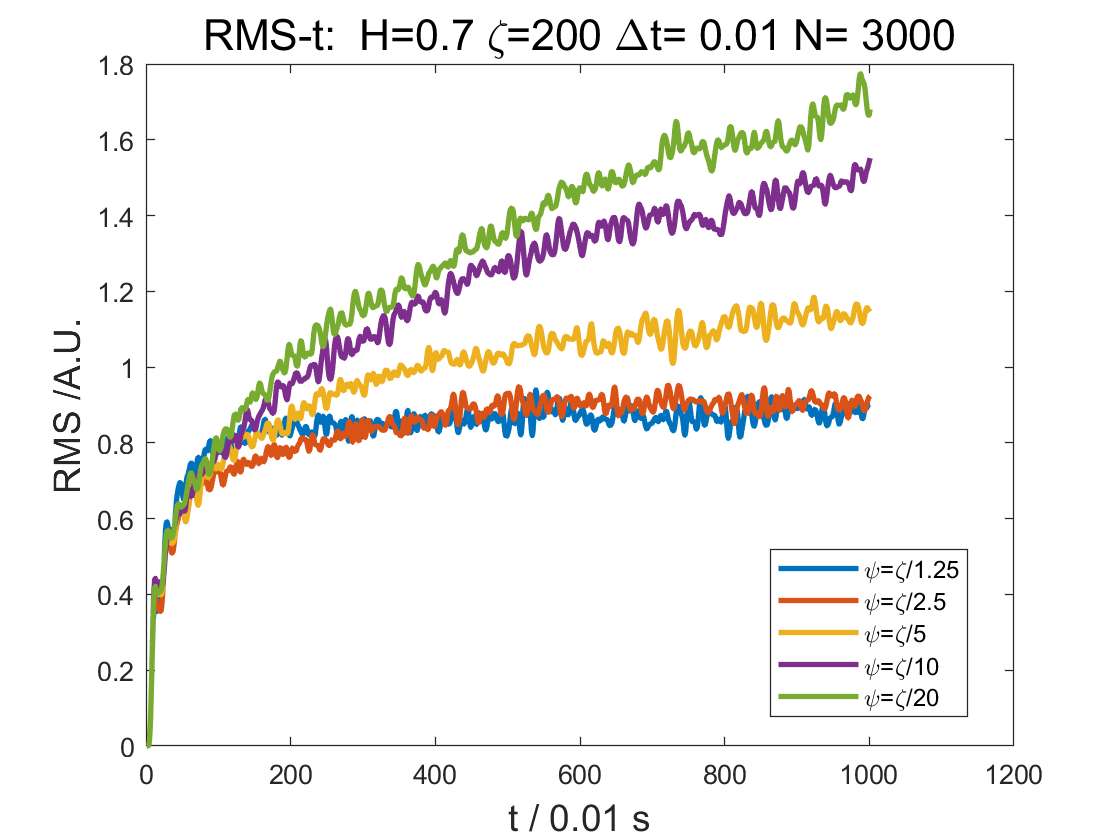

row = 12

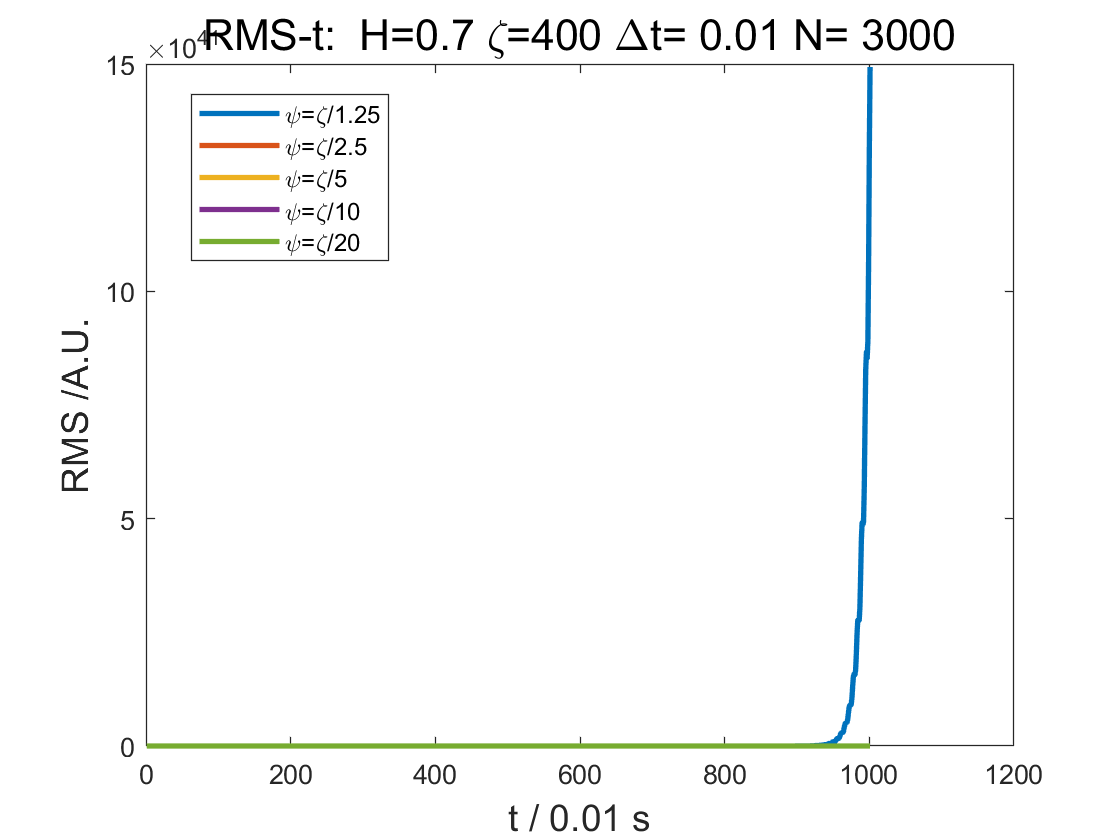

row = 13

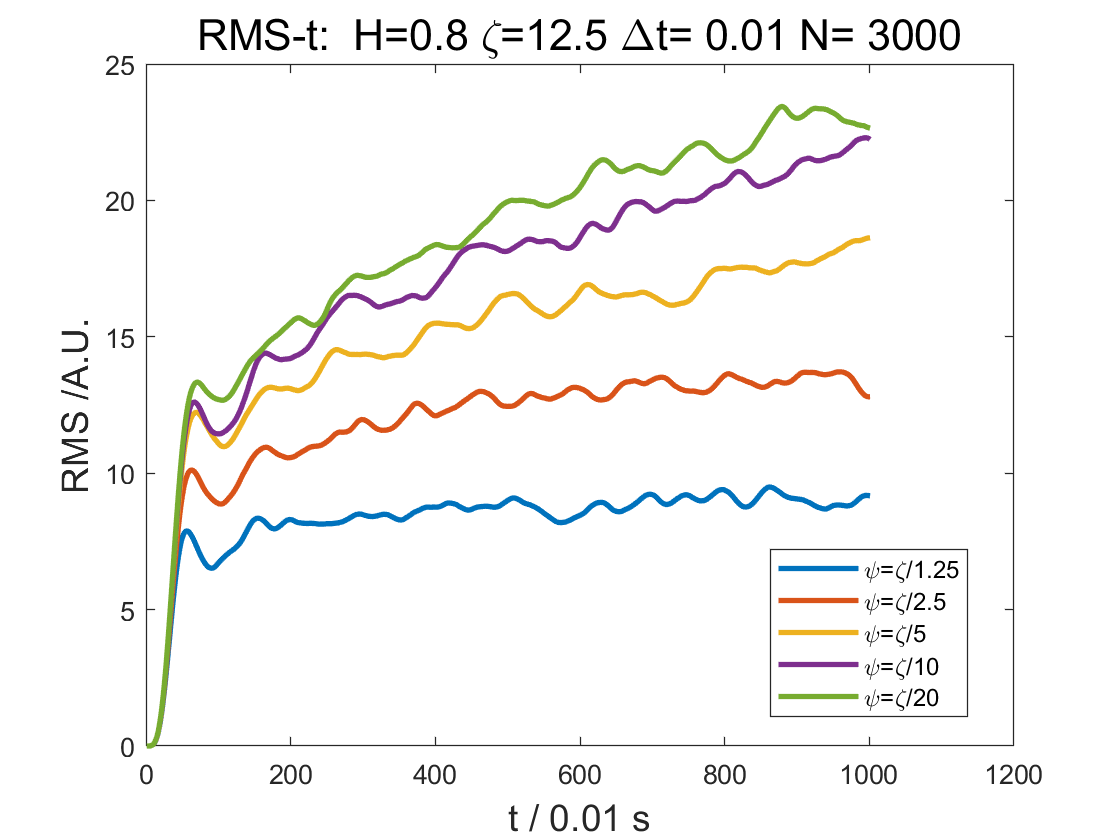

row = 14

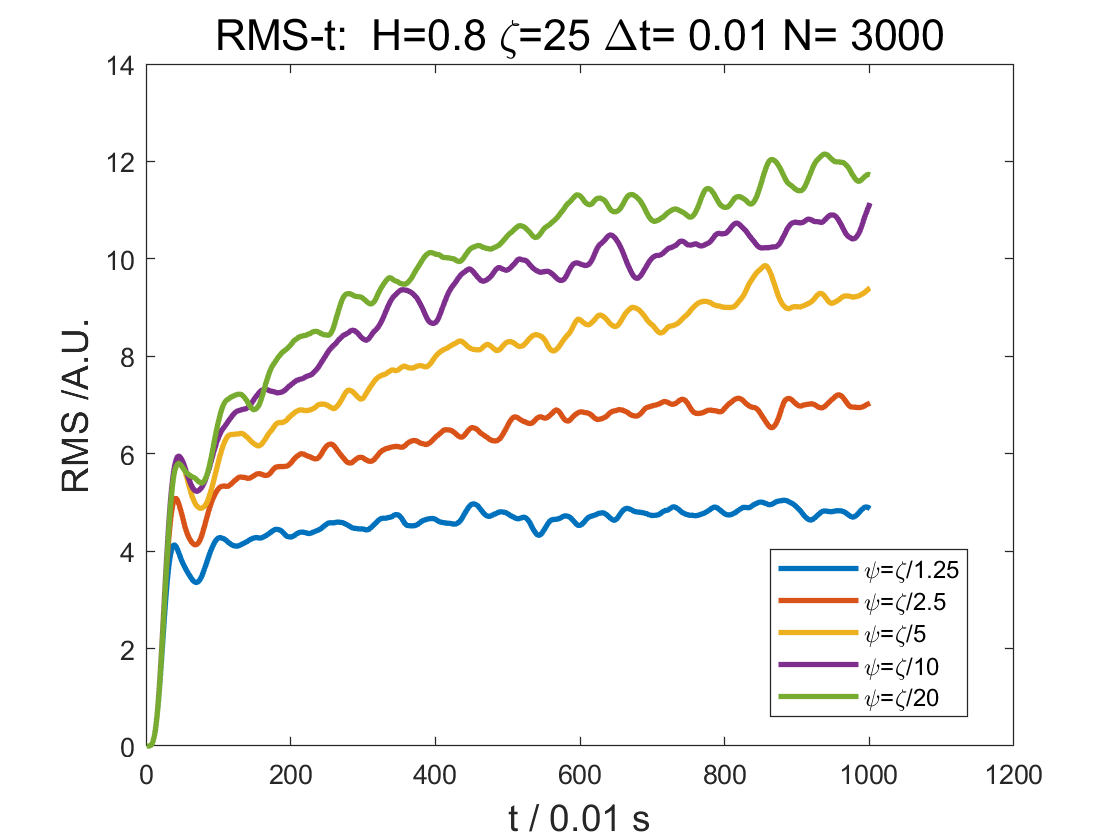

row = 15

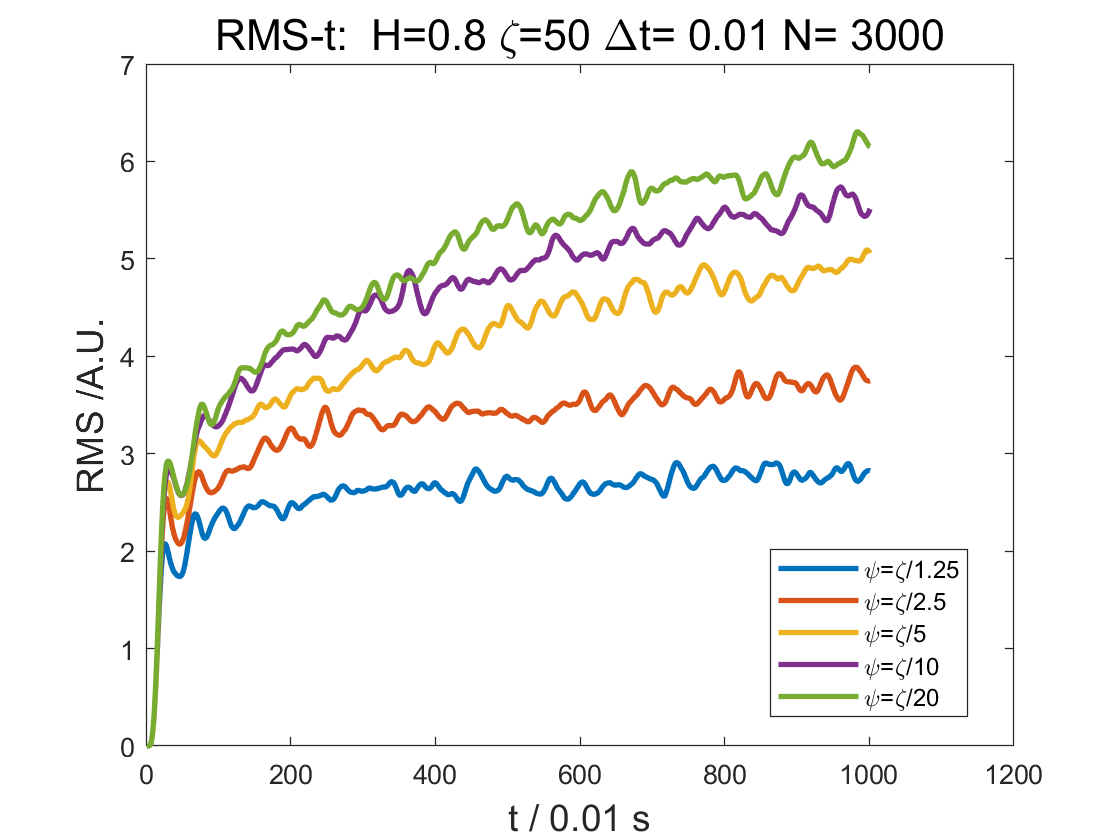

row = 16

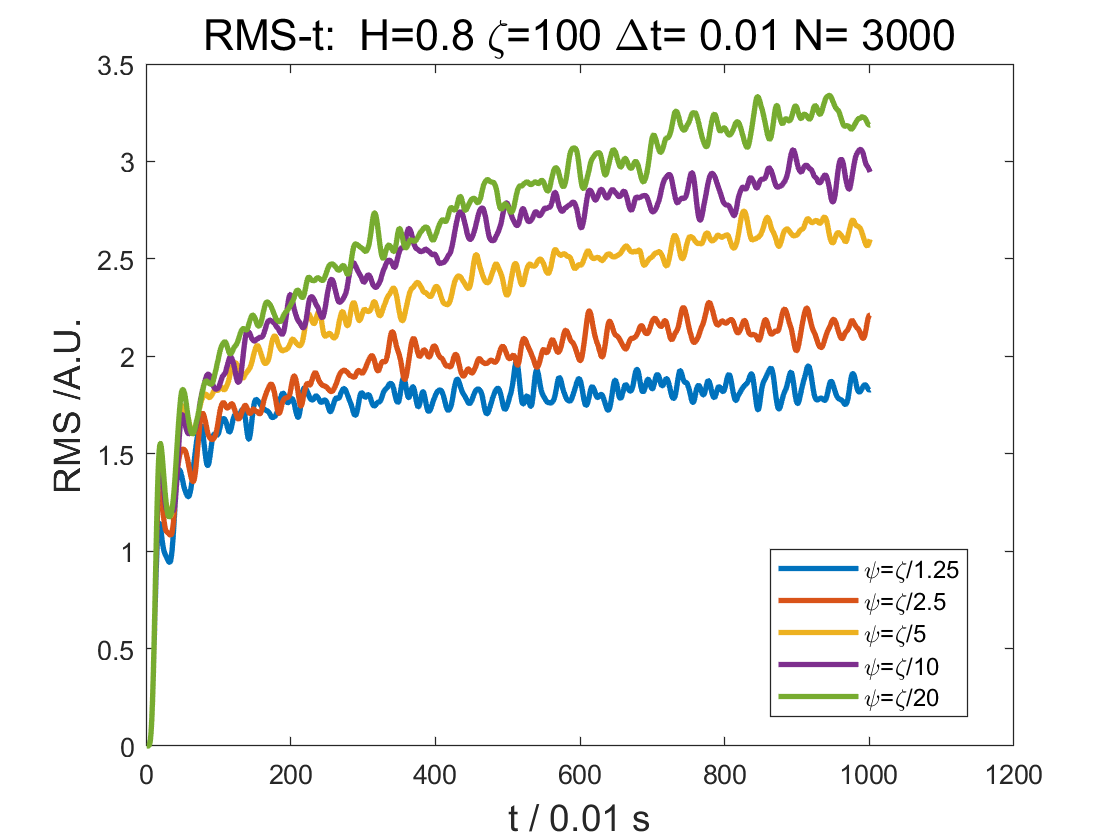

row = 17

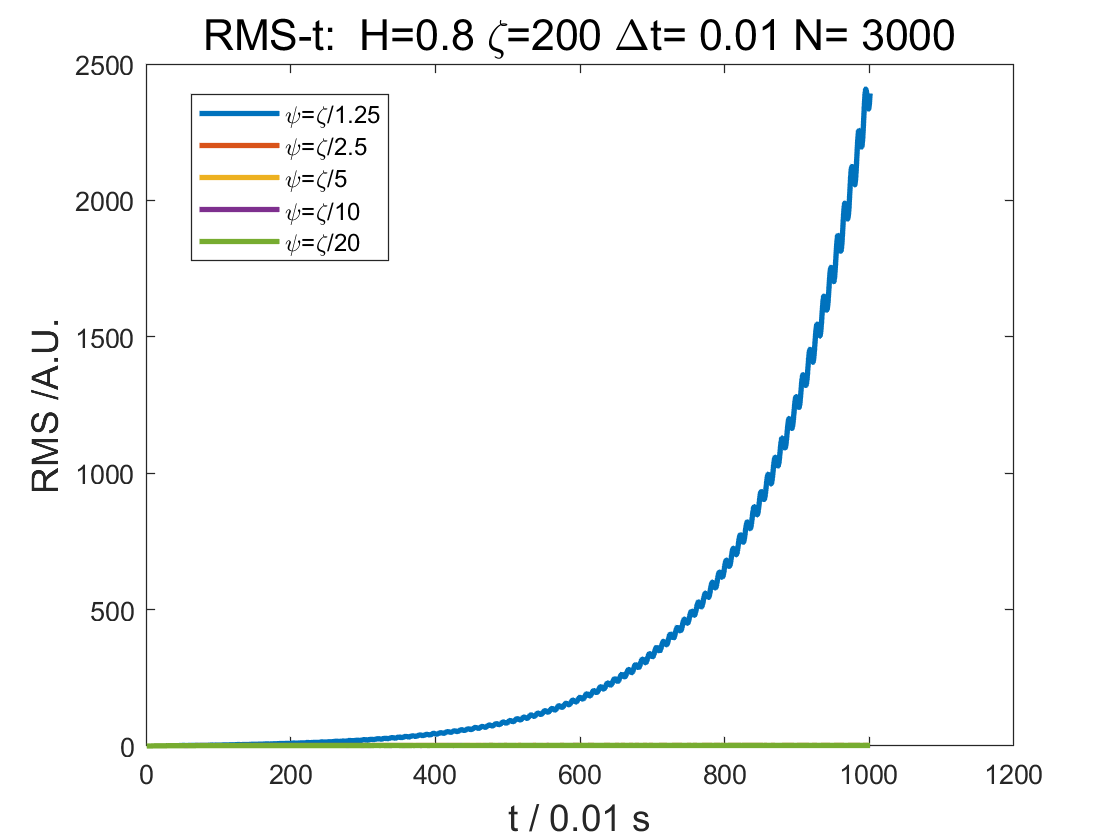

row = 18

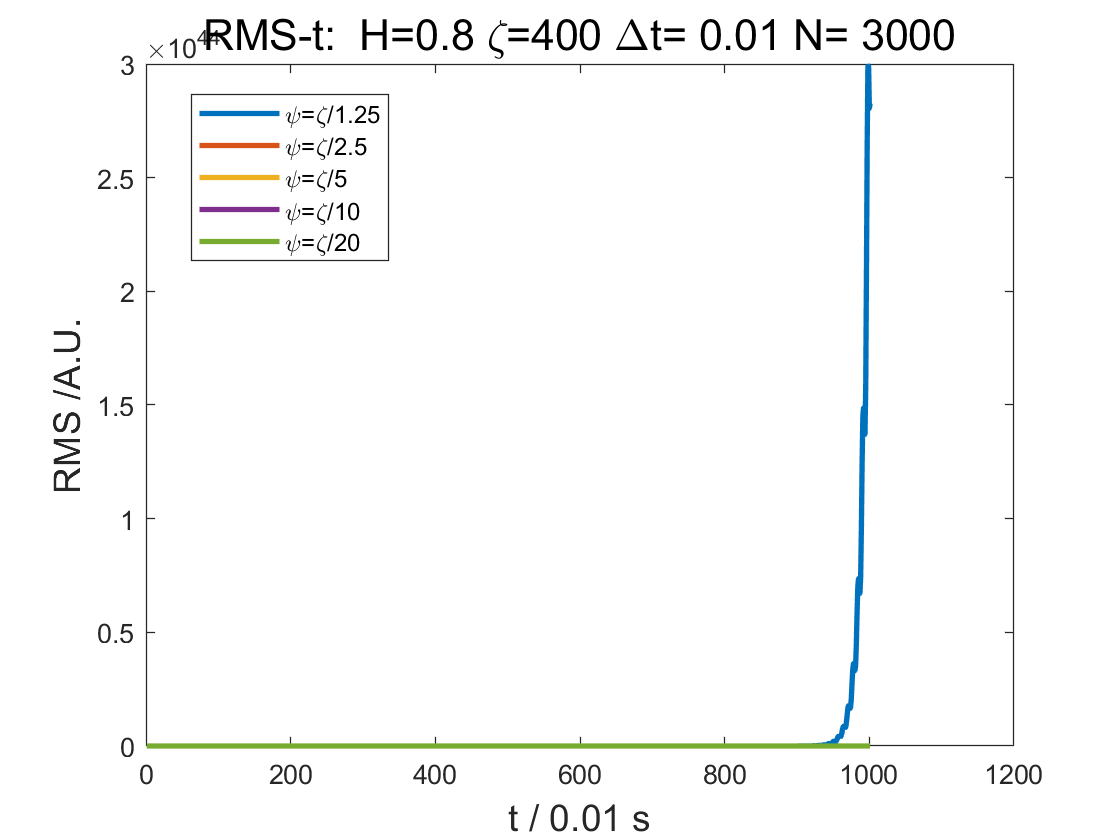

row = 19

X=1:1001;
row=1;
for H=[0.6,0.7,0.8]
    for zeta=zetastore
        figure
        figure_RMS=plot(X,RMSstorage(:,row,1),X,RMSstorage(:,row,2),X ...
            ,RMSstorage(:,row,3),X,RMSstorage(:,row,4),X ...
            ,RMSstorage(:,row,5),'LineWidth',2);
        title(['RMS-t: ',' H=',num2str(H),' \zeta=',num2str(zeta),' \Deltat= ',num2str(delta), ...
            ' N= ',num2str(Total_experiment_number)],'FontSize',16);
        xlabel(['t / ',num2str(delta),' s'],'FontSize',14);
        ylabel('RMS /A.U.','FontSize',14);
        legend('\psi=\zeta/1.25','\psi=\zeta/2.5','\psi=\zeta/5','\psi=\zeta/10','\psi=\zeta/20',"Location","best");
        saveas(gcf,['v4_1\processed_image\RMS','.H=',num2str(H),'.zeta=',num2str(zeta),'.delta=',num2str(delta),'.N=',num2str(Total_experiment_number),'.jpg'])
        row=row+1
    end
end

## Explosion part processing

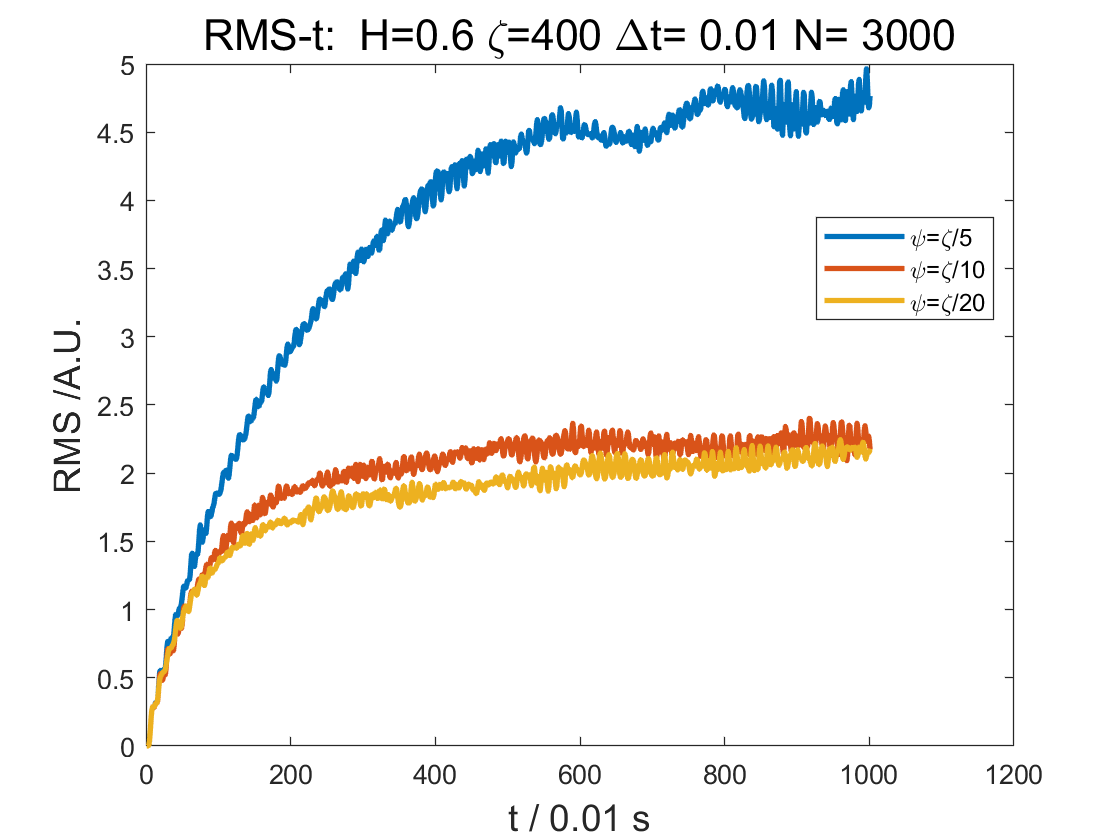

boom!


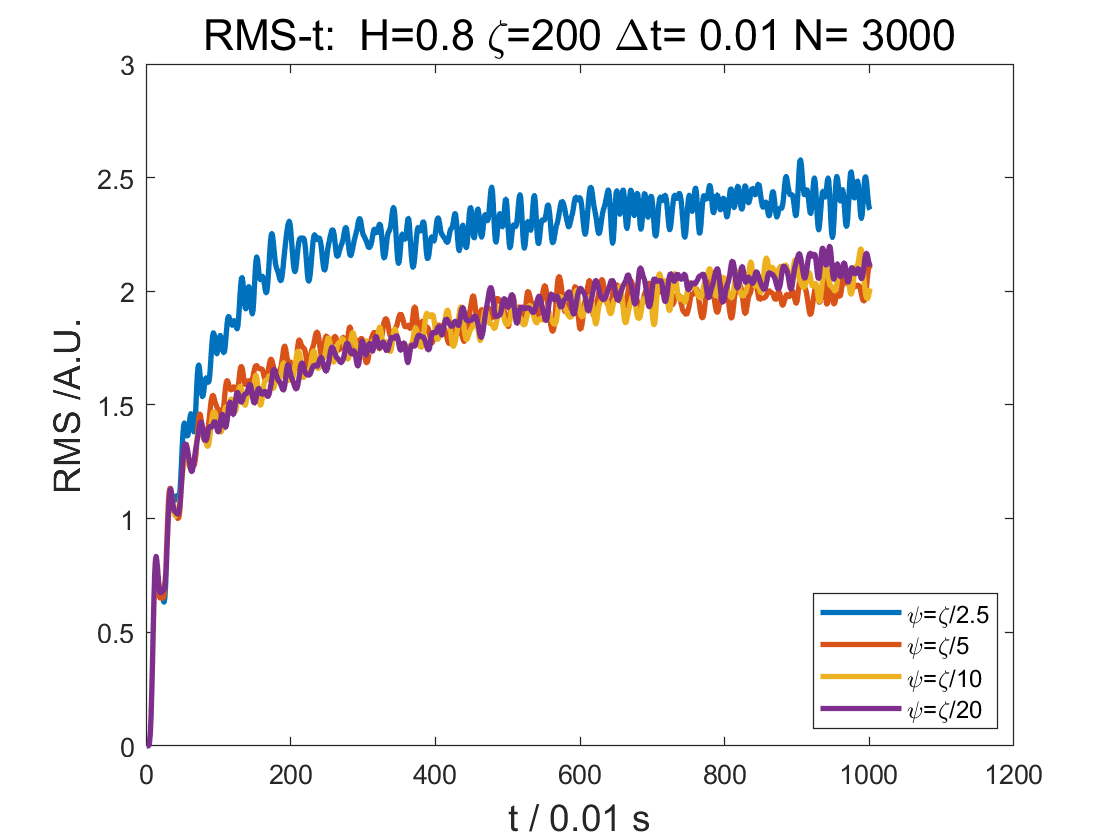

boom!


X=1:1001;
row=1;
for H=[0.6,0.7,0.8]
    for zeta=zetastore
        if RMSstorage(1001,row,5)>=100
            disp('boom!')
        elseif RMSstorage(1001,row,4)>=100
            disp('nearly')
            figure
            figure_RMS=plot(X,RMSstorage(:,row,5),'LineWidth',2);
            title(['RMS-t: ',' H=',num2str(H),' \zeta=',num2str(zeta),' \Deltat= ',num2str(delta), ...
                ' N= ',num2str(Total_experiment_number)],'FontSize',16);
            xlabel(['t / ',num2str(delta),' s'],'FontSize',14);
            ylabel('RMS /A.U.','FontSize',14);
            legend('\psi=\zeta/20',"Location","best");
            saveas(gcf,['v4_1\processed_image\RMS1','.H=',num2str(H),'.zeta=',num2str(zeta),'.delta=',num2str(delta),'.N=',num2str(Total_experiment_number),'.jpg'])
        elseif RMSstorage(1001,row,3)>=100
            figure
            figure_RMS=plot(X,RMSstorage(:,row,4),X ...
                ,RMSstorage(:,row,5),'LineWidth',2);
            title(['RMS-t: ',' H=',num2str(H),' \zeta=',num2str(zeta),' \Deltat= ',num2str(delta), ...
                ' N= ',num2str(Total_experiment_number)],'FontSize',16);
            xlabel(['t / ',num2str(delta),' s'],'FontSize',14);
            ylabel('RMS /A.U.','FontSize',14);
            legend('\psi=\zeta/10','\psi=\zeta/20',"Location","best");
            saveas(gcf,['v4_1\processed_image\RMS2','.H=',num2str(H),'.zeta=',num2str(zeta),'.delta=',num2str(delta),'.N=',num2str(Total_experiment_number),'.jpg'])
        elseif RMSstorage(1001,row,2)>=100
            figure
            figure_RMS=plot(X ...
                ,RMSstorage(:,row,3),X,RMSstorage(:,row,4),X ...
                ,RMSstorage(:,row,5),'LineWidth',2);
            title(['RMS-t: ',' H=',num2str(H),' \zeta=',num2str(zeta),' \Deltat= ',num2str(delta), ...
                ' N= ',num2str(Total_experiment_number)],'FontSize',16);
            xlabel(['t / ',num2str(delta),' s'],'FontSize',14);
            ylabel('RMS /A.U.','FontSize',14);
            legend('\psi=\zeta/5','\psi=\zeta/10','\psi=\zeta/20',"Location","best");
            saveas(gcf,['v4_1\processed_image\RMS3','.H=',num2str(H),'.zeta=',num2str(zeta),'.delta=',num2str(delta),'.N=',num2str(Total_experiment_number),'.jpg'])
        elseif RMSstorage(1001,row,1)>=100
            figure
            figure_RMS=plot(X,RMSstorage(:,row,2),X ...
                ,RMSstorage(:,row,3),X,RMSstorage(:,row,4),X ...
                ,RMSstorage(:,row,5),'LineWidth',2);
            title(['RMS-t: ',' H=',num2str(H),' \zeta=',num2str(zeta),' \Deltat= ',num2str(delta), ...
                ' N= ',num2str(Total_experiment_number)],'FontSize',16);
            xlabel(['t / ',num2str(delta),' s'],'FontSize',14);
            ylabel('RMS /A.U.','FontSize',14);
            legend('\psi=\zeta/2.5','\psi=\zeta/5','\psi=\zeta/10','\psi=\zeta/20',"Location","best");
            saveas(gcf,['v4_1\processed_image\RMS4','.H=',num2str(H),'.zeta=',num2str(zeta),'.delta=',num2str(delta),'.N=',num2str(Total_experiment_number),'.jpg'])
        end
        row=row+1;
    end
end